# Risk Management Dashboard

Tha main porpuse of this live scrip is documenting the approach used to develop the metrics and visuals showed in the dashboard.

## Parameters

We simulate, separately, short ang long position portfolio, based on known variance and mean parameters $\left(\mu \;,\sigma {\;}^2 \right)$ and normal distribution for the returns. The returns are going to be correlated based on a defined correlation matrix.

We define $n$ as the number of scenarios to simulate and a time horizon $t$, measured in years.

n = 10000;
t = 1/12;
VaRp = 0.05;

## Log return distribution assumptions

We buld a structure with the expected yearly log-returns, divided by risk free rate component and the exchange rate change, of each portfolio. The parameters are aggreegated estimations that can be calculated.

% Expected log-returns
param.('E_LongRFRate') = 0.008;
param.('E_ShortRFRate') = 0.008;
param.('E_LongExcRateChng') = 0.004;
param.('E_ShortExcRateChng') = 0.003;

% Standard deviation
param.('SD_LongRFRate') = 0.05;        %(1)
param.('SD_ShortRFRate') = 0.05;       %(2)
param.('SD_LongExcRateChng') = 0.05;   %(3)
param.('SD_ShortExcRateChng') = 0.05;  %(4)

% Correlation matrix
param.('Correlations') = [ 1.0  0.7 -0.2 -0.1;
                           0.7  1.0 -0.1 -0.2;
                          -0.2 -0.1  1.0  0.8;
                          -0.1 -0.2  0.8  1.0];
                      
% Covarianve matrix
param.('Covariance') = corr2cov([param.SD_LongRFRate, param.SD_ShortRFRate, ...
                                 param.SD_LongExcRateChng, param.SD_ShortExcRateChng], ...
                             param.Correlations);

Portfolio initial values, in million USD stored into a variable type struct.

portfolio = struct();
portfolio.Long = struct();
portfolio.Short = struct();

portfolio.Long.Initial = 110;
portfolio.Short.Initial = 100;

## Simulating scenarios

We are going to simulate portfolio valuation and portion what portion has maturity at time $t$.

### Porfolio log returns

Simulating $n$ times the log returns of the long and short portfolios at time $t$.

% Simulating cashflows
Z = mvnrnd(t*[param.SD_LongRFRate, param.SD_ShortRFRate, ...
    param.SD_LongExcRateChng, param.SD_ShortExcRateChng], ...
    t*param.Covariance, n);

% Calculating initial and final values
portfolio.Long.Final = portfolio.Long.Initial*exp(Z(:,1)+Z(:,3));
portfolio.Short.Final = portfolio.Short.Initial*exp(Z(:,2)+Z(:,4));
portfolio.Net.Initial = portfolio.Long.Initial - portfolio.Short.Initial;
portfolio.Net.Final = portfolio.Long.Final - portfolio.Short.Final;

% VaR Calculation
VaR = quantile(portfolio.Net.Final,VaRp,'all');

### Portfolio distribution

Histogram of portfolio scenarios based on the simulated log returns.

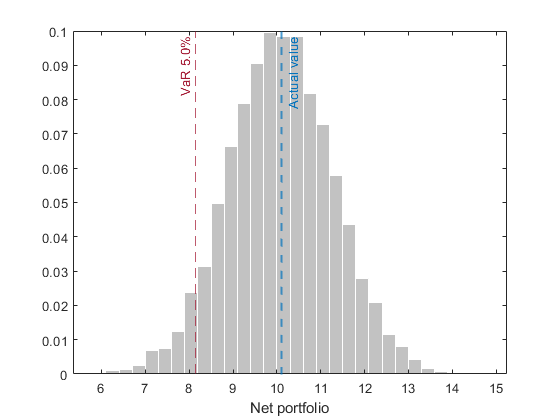

h1 = plotHistogram(portfolio.Net.Final, 10.1, 30, VaRp, VaR);

### Portfolio cashflows

Simulating $n$ times the cashflows of the short and long portfolios in the interval $\left(0,t\right)$. The cashflows are driven only by maturity cashflows and reinvestment, based on some big but simple assumptions.

% Average portion with maturity at the first month
muMaturity = 1/11;
maturityCF = muMaturity.*(1+(mvnrnd([0 0], [1 0; 0 1], n))*0.03);

% Portfolio valuation
portfolio.Long.Valuation = (portfolio.Long.Final-portfolio.Long.Initial).*(1-maturityCF(:,1));
portfolio.Short.Valuation = (portfolio.Short.Final-portfolio.Short.Initial).*(1-maturityCF(:,2));
portfolio.Net.Valuation = portfolio.Long.Valuation - portfolio.Short.Valuation ;

% Matirity cashflows
portfolio.Long.MaturityCF = maturityCF(:,1).*portfolio.Long.Final;
portfolio.Short.MaturityCF = maturityCF(:,2).*portfolio.Short.Final;
portfolio.Net.MaturityCF = portfolio.Long.MaturityCF - portfolio.Short.MaturityCF;

% Opened position cashflows
portfolio.Long.OpenCF = portfolio.Long.Final - (portfolio.Long.Initial + portfolio.Long.Valuation -...
    portfolio.Long.MaturityCF);
portfolio.Short.OpenCF = portfolio.Short.Final - (portfolio.Short.Initial + portfolio.Short.Valuation -...
    portfolio.Short.MaturityCF);
portfolio.Net.OpenCF = portfolio.Long.OpenCF - portfolio.Short.OpenCF;

% Net cashflows
portfolio.Long.NetCF = portfolio.Long.MaturityCF - portfolio.Long.OpenCF;
portfolio.Short.NetCF = portfolio.Short.MaturityCF - portfolio.Short.OpenCF;
portfolio.Net.NetCF = portfolio.Long.NetCF - portfolio.Short.NetCF;


### Cashflows against valuation

We plot the value change of the portfolio against the cashflows, finding the ellipse that contains a defined portion of the dots (95% in this case).

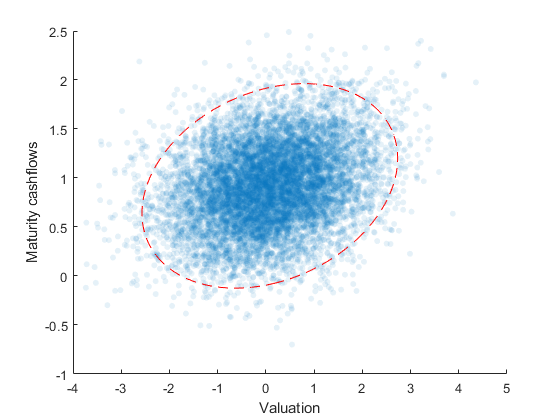

s1 = plotErrorEllipse(portfolio.Net.Valuation, portfolio.Net.MaturityCF, 0.95);

## Functions

In this section we defined a couple of functions we used to build the dashboard plots.

### Error ellipse function

This function plots X-Y and a confidence ellipse which contains 100*(1-p)% of the pairs (x,y).    

function s1 = plotErrorEllipse(X, Y, p)
    mu = mean([X Y]);
    Sigma = cov([X Y]);
    s = -2 * log(1 - p);
    [V, D] = eig(Sigma * s);

    t = linspace(0, 2 * pi);
    a = (V * sqrt(D)) * [cos(t(:))'; sin(t(:))'];
    
    s1 = scatter(X, Y, 'filled');
    s1.MarkerFaceAlpha = 0.1;
    s1.SizeData = 20;
    xlabel('Valuation');
    ylabel('Maturity cashflows');
    hold on
    plot(a(1, :) + mu(1), a(2, :) + mu(2), '--r');
    hold off
end

### Scenario histogram

This function plots a histogram that shows the value distribution for all the portfolio simulations.

function h1 = plotHistogram(portValues, actualValue, bins, VaRp, VaR)
    h1 = histogram(portValues, bins);
    h1.Normalization = 'probability';
    h1.EdgeColor = 'w';
    h1.FaceColor = [0.6 0.6 0.6];
    hold on;
    xline(VaR,'--',...
        {[sprintf('VaR %.1f', 100*VaRp) '%']},...
        'LabelHorizontalAlignment','left',...
        'Color', [0.6350 0.0780 0.1840]);
    xline(actualValue, ...
        '--', 'Actual value', 'Color', [0 0.4470 0.7410], 'LineWidth', 1.5); 
    xlabel('Net portfolio');
    hold off;
end